# **Vision Artificial. GIEC.**

# **Sistemas de Vision Artificial. GIC.**

**Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos.**

**Departamento de Electrónica. Universidad de Alcalá.**

**Hecho por:**

- Patricia Cuesta Ruiz

- Laura Mambrilla Moreno

# Tema 5: ejercicio 01 - Calibración de una cámara

**Nota**: el tamaño del cuadrado del tablero de ajedrez es de **21 milímetros**.

clc;
clear all;
close all;

Step 1) Load data set.

% image_num = 3;
% image_name = sprintf('checkerboard_pattern/image%d.png',image_num);
% image = imread(image_name);
% imageUndistorted = undistortImage(image,cameraParams);
% imshowpair(image,imageUndistorted,'montage')  

Se pide:

         1. Usa la aplicación [**Camera Calibrator**](https://es.mathworks.com/help/vision/ref/cameracalibrator-app.html) para estimar los parámetros intrínsecos, extrínsecos y de distorsión de la cámara. Escriba `cameraCalibrator` en la línea de comandos de Matlab o selecciónelo en la pestaña de Aplicaciones (APPS) de Matlab. Siga las instrucciones de este enlace para realizar la calibración: [https://es.mathworks.com/help/vision/ug/single-camera-calibrator-app.html](https://es.mathworks.com/help/vision/ug/single-camera-calibrator-app.html)  **NOTA**: utilice una webcam y el patrón del tablero de ajedrez o directamente las imágenes de la carpeta "`/chessboard_pattern`". 

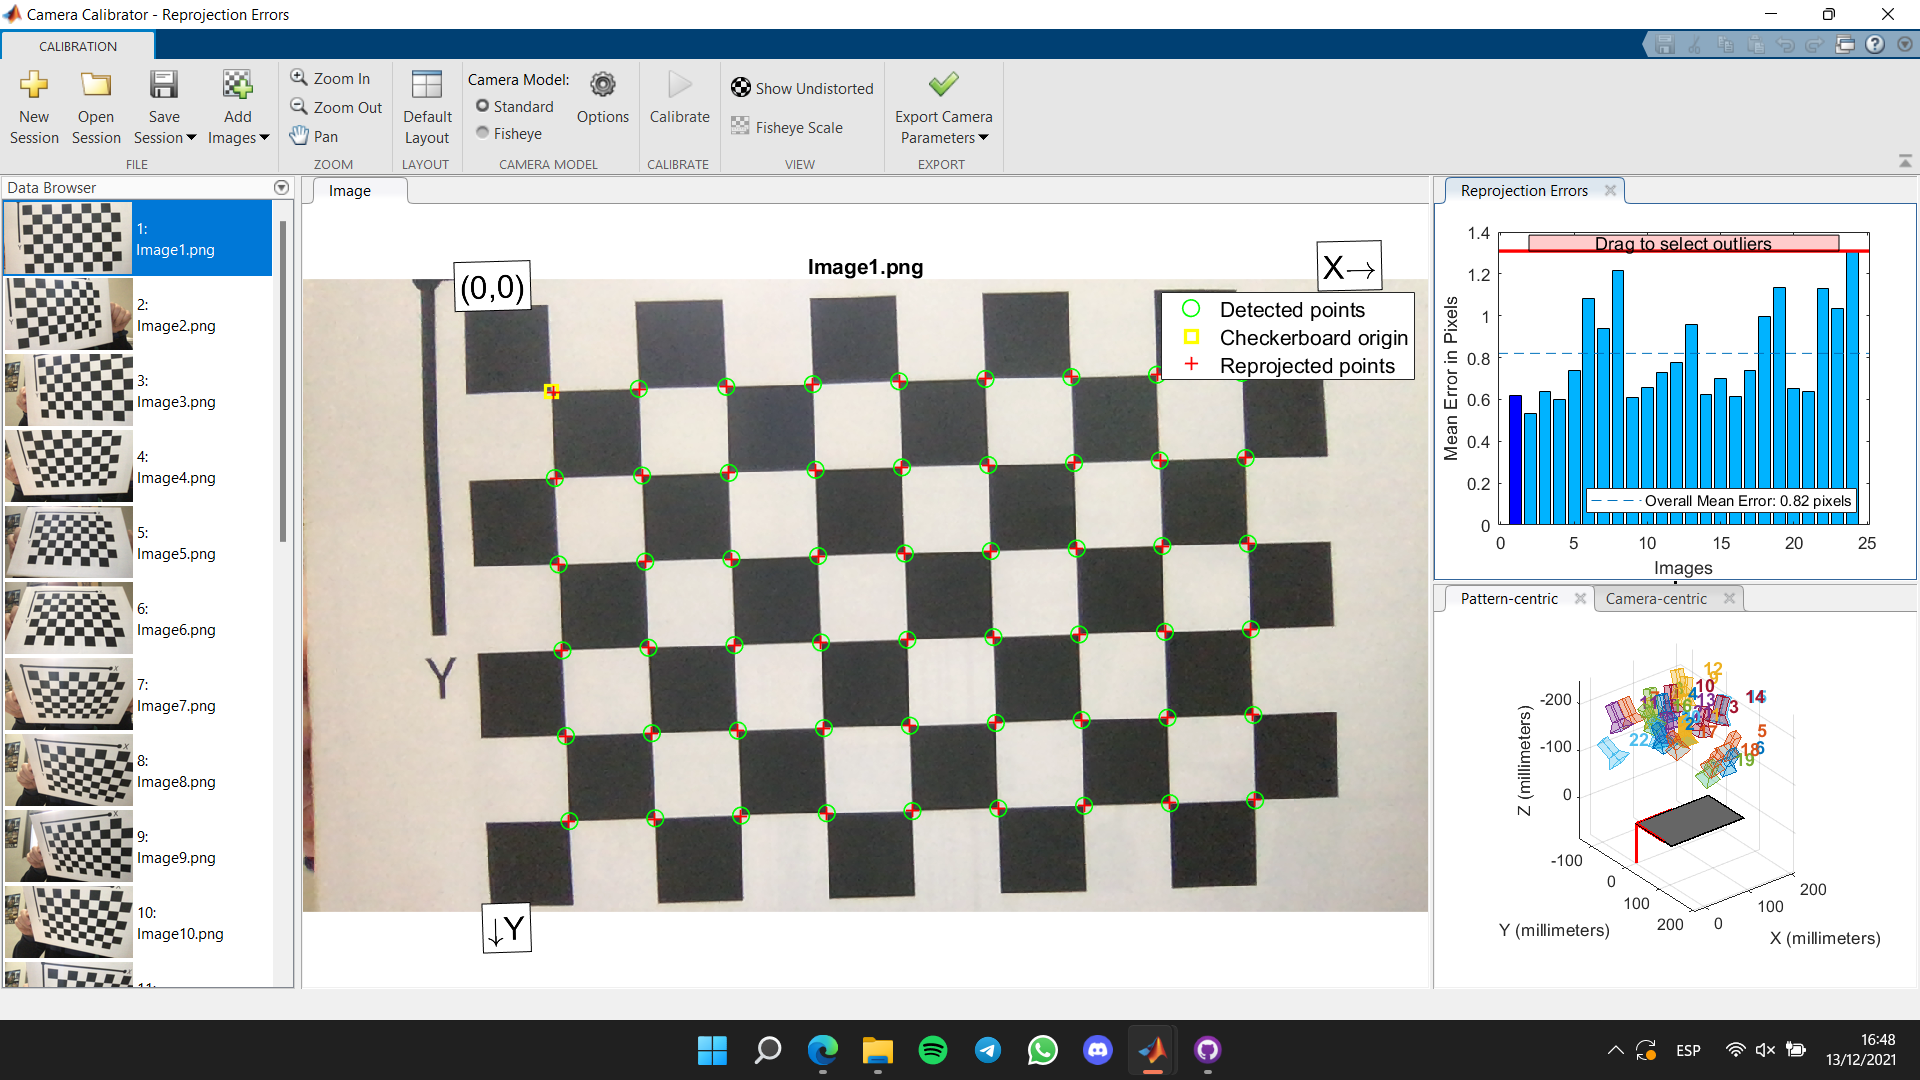

         2. Una vez que se ha realizado una calibración correcta, exporte los parámetros de calibración al espacio de trabajo (Workspace) con el nombre `cameraParams`.

**Posteriormente, hemos exportado los parámetros de la cámara al *****workspace*****. **

**Para no tener que calibrar la cámara cada vez que abrimos el ejercicio, hemos guardado los parámetros de la cámara utilizando:**

- `save 'cameraParams.mat' cameraParams `**si se hace en la *****Command Window*****.**

- `save('cameraParams.mat', cameraParams) `**si se ejecuta en un bloque de código.**

**Si se desea cargar los parámetros de calibración guardados con anterioridad:**

- `load 'cameraParams.mat' `**si se hace en la *****Command Window*****.**

- `load('cameraParams.mat') `**si se ejecuta en un bloque de código.**

load('cameraParams.mat');

         3. Obtenga la matriz de parámetros intrínsecos e identifique los distintos parámetros. Cargue una de las imágenes utilizadas para la calibración y obtebga los parámetros extrínsecos de esta imagen. ¿si cargase otra imagen diferente cambiaría alguno de los parámetros intrínsecos o extrínsecos? justifique la respuesta.

intrinsicParams = cameraParams.IntrinsicMatrix

intrinsicParams =   951.2453         0         0
         0  947.3110         0
  649.3419  358.9405    1.0000


rotationMatrix2 = cameraParams.RotationMatrices(:,:,2) % matriz de rotación de la imagen 2

rotationMatrix2 =     0.9262   -0.0638    0.3716
    0.0650    0.9978    0.0092
   -0.3714    0.0156    0.9284


translationVector2 = cameraParams.TranslationVectors(2,:) % vector de translación de la imagen 2

translationVector2 =   -92.5943  -54.6022  196.7946


**Si se cargase una imagen distinta no se producirían cambios en los parámetros intrínsecos, pero sí en los parámetros extrínsecos. Esto se debe a que los parámetros intrínsecos definen las características internas del sistema de la cámara y los extrínsecos describen la transformación geométrica independientemente de la cámara. Es decir,  solo hay una única matriz intrínseca común para todas las imágenes que definen las características internas independientemente de la cámara, mientras que hay una matriz de rotación y un vector de translación para cada una de las 24 imágenes que describen la transformación geométrica independientemente de la cámara.**

         4. Cargue una de las imágenes utilizadas para la calibración y obtenga la imagen no distorsionada con la función `undistorsionImage. `Proyecte los puntos de una pirámide 3D en esta imagen no distorsionada usando la función `worldToImage`. Nota: uno de los vértices de la pirámide debe estar situado en el punto de las coordenadas del mundo (X=0,Y=0,Z=0) y el tamaño de la base de la pirámide debe ocupar cuadrados del patrón del tablero de ajedrez y la altura debe ser 1.5 veces la longitud de un lado de la base.

Nota: la matriz de parámetros intrínsecos es: 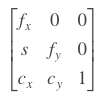

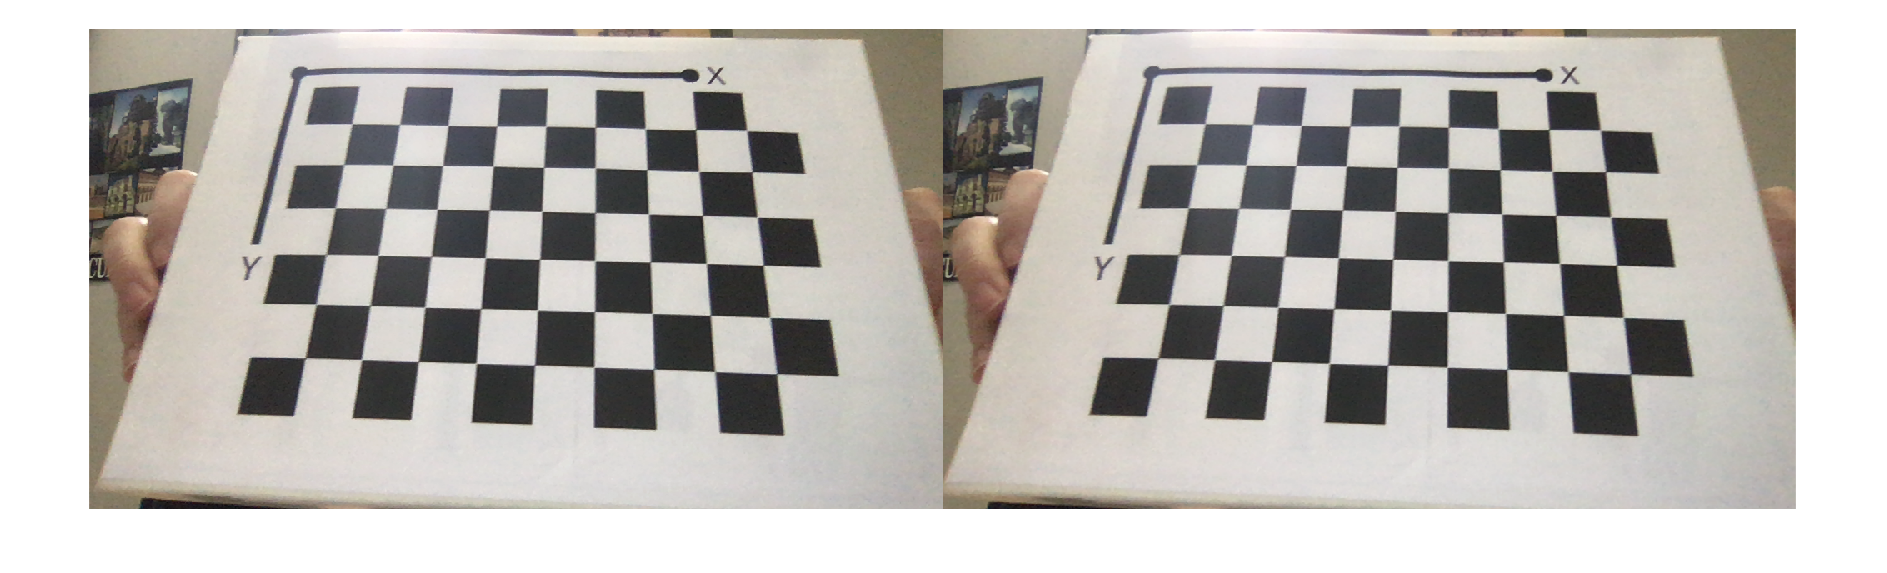

image_num = 5;
image_name = sprintf('checkerboard_pattern/image%d.png', image_num);
image = imread(image_name);
imageUndistorted = undistortImage(image, cameraParams);
imshowpair(image, imageUndistorted, 'montage') 

rotationMatrix = cameraParams.RotationMatrices(:,:,image_num) % matriz de rotación de 'image_num'

rotationMatrix =     0.9976    0.0270   -0.0632
   -0.0511    0.9058   -0.4205
    0.0459    0.4227    0.9051


translationVector = cameraParams.TranslationVectors(image_num,:) % vector de translación de 'image_num'

translationVector =   -73.5251  -62.4509  275.0285


**Hemos implementado el siguiente código para que la modificación de algunas características de la pirámide (*****numSquares ***** y *****h*****) sea menos tediosa y más dinámica.**

squareSize = 21;               % longitud de cada cuadrado (celda)
numSquares = 2;                % número de celdas
len = squareSize * numSquares; % longitud del lado de la base de la pirámide
h = 1.5;                       % proporción para la altura de la pirámide (respecto a la base)

**Además, hemos añadido un offset para x, y y z para poder desplazar la pirámide en cualquier dimensión con respecto al tablero simplemente cambiando el valor númerico en las siguientes líneas de código (líneas 24, 25 y 26).**

x = squareSize * 1; % offset de x
y = squareSize * 1; % offset de y
z = squareSize * 0; % offset de z

pt1 = [x y -z];                     % vértice arriba izquierda
pt2 = [x+len y -z];                 % vértice arriba derecha
pt3 = [x y+len -z];                 % vértice abajo izquierda
pt4 = [x+len y+len -z];             % vértice abajo derecha
pt5 = [x+len/2 y+len/2 -(z+len*h)]; % vértice pirámide
worldPoints = [pt1; 
               pt2; 
               pt3; 
               pt4; 
               pt5]

worldPoints =     21    21     0
    63    21     0
    21    63     0
    63    63     0
    42    42   -63


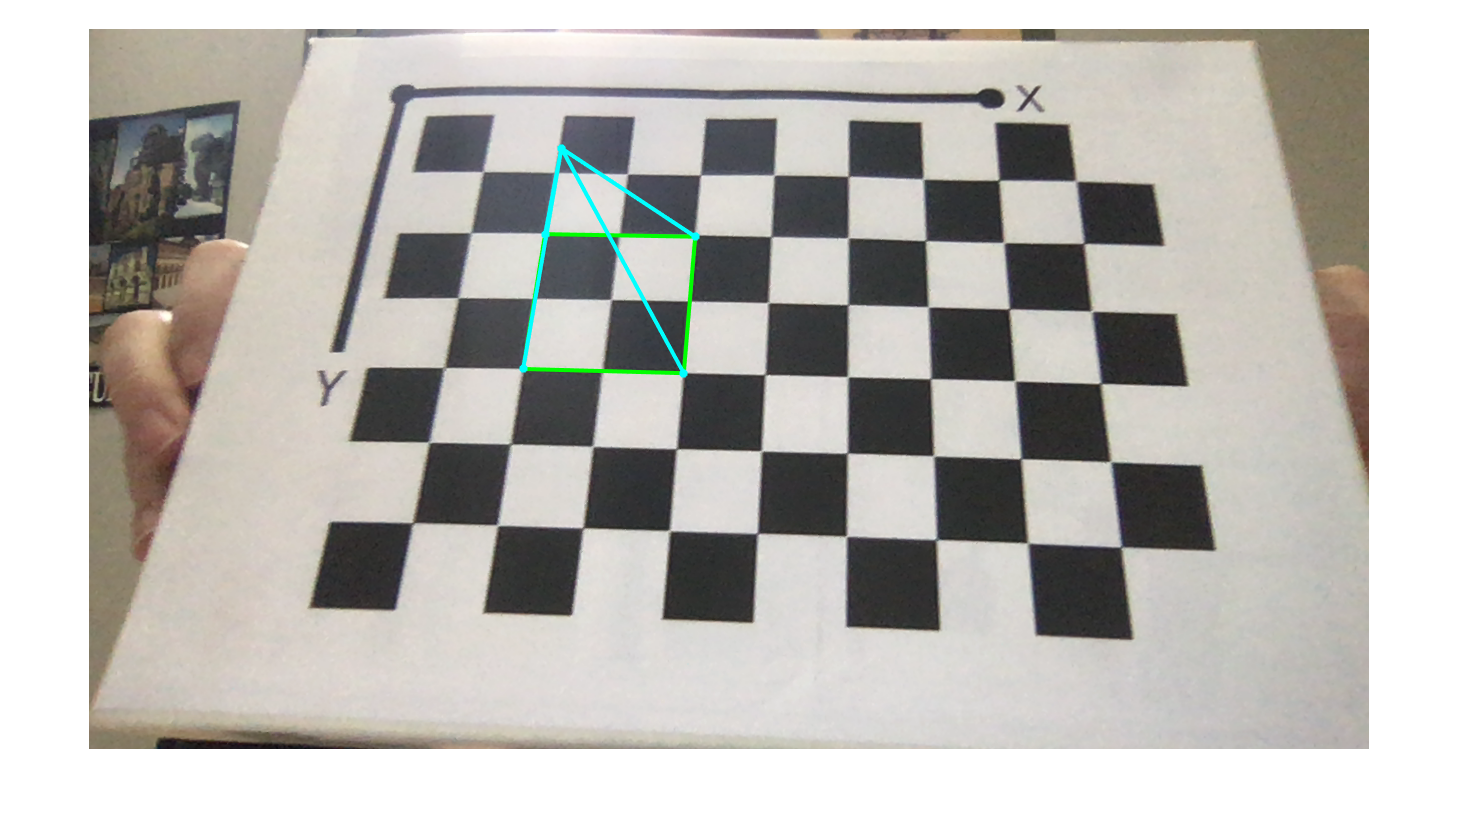


imagePoints = worldToImage(cameraParams, rotationMatrix, translationVector, worldPoints);
figure;
imshow(imageUndistorted);
hold on;
% pt1 - pt2
plot([imagePoints(1,1), imagePoints(2,1)], [imagePoints(1,2), imagePoints(2,2)], 'g*-', 'LineWidth', 3);
% pt1 - pt3
plot([imagePoints(1,1), imagePoints(3,1)], [imagePoints(1,2), imagePoints(3,2)], 'g*-', 'LineWidth', 3);
% pt1 - pt5
plot([imagePoints(1,1), imagePoints(5,1)], [imagePoints(1,2), imagePoints(5,2)], 'c*-', 'LineWidth', 3);
% pt2 - pt4
plot([imagePoints(2,1), imagePoints(4,1)], [imagePoints(2,2), imagePoints(4,2)], 'g*-', 'LineWidth', 3);
% pt2 - pt5
plot([imagePoints(2,1), imagePoints(5,1)], [imagePoints(2,2), imagePoints(5,2)], 'c*-', 'LineWidth', 3);
% pt3 - pt4
plot([imagePoints(3,1), imagePoints(4,1)], [imagePoints(3,2), imagePoints(4,2)], 'g*-', 'LineWidth', 3);
% pt3 - pt5
plot([imagePoints(3,1), imagePoints(5,1)], [imagePoints(3,2), imagePoints(5,2)], 'c*-', 'LineWidth', 3);
% pt4 - pt5
plot([imagePoints(4,1), imagePoints(5,1)], [imagePoints(4,2), imagePoints(5,2)], 'c*-', 'LineWidth', 3);
hold off;